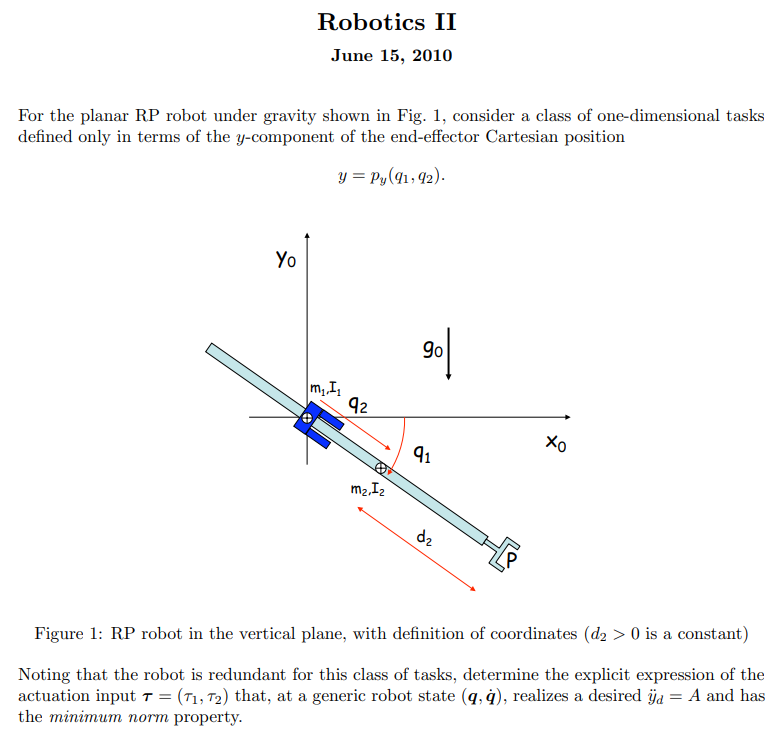

% % This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,1];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rp';'xx';sigmaD]

R2Robot = 3×2 char array
    'rp'
    'xx'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;

z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[l(1),dc(1)],[0,0]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=1;
z.xyonly=false

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[l1    dc1]  [0 0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % 

% % 
% % PC_EEShort.J
% % PC_EEShort.f
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[l1    dc1]  [0 0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {[1×1 struct]}
              xyx_offset: []
      global_q

si falla aquí está el error


$$a = l_{1}$$

d = 0

anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & {\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ 0 & {\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & -{\dot{q}}_{1}\\ {\dot{q}}_{1} & 0 \end{array}\right)$$

$$T = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: (I1*q_dot_1^2)/2 + (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2
    Ti: [(I1*q_dot_1^2)/2    (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: q_1
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: (I1*q_dot_1^2)/2 + (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2
                     Ti: [(I1*q_dot_1^2)/2    (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2]
                      M: [2×2 sym]


p_y=subs(Pc(2,2),q(2),q(2)+z.dc(2))

$$p\_y = \sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right)$$

pd={sym('pd_1_',[1,1],'real')};
% z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
z.task_defined={struct('f',[p_y],'pd_',pd{1})} ;%pc is note necessary
%
z.task_defined

ans = 1×1 cell array
    {1×1 struct}


% % VarShortRobot.M
% % angle_desired=[0,0]
% % % xyonly=true
[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[l1    dc1]  [0 0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {[1×1 struct]}
              xyx_offset: []
      global_q

si falla aquí está el error


$$a = l_{1}$$

d = 0

anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


num_new_tasks = 1

$$To\_derive = \sin\left(q_{1}\left(t\right)\right)\,\left({\mathrm{dc}}_{2}+q_{2}\left(t\right)\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)


z_derivated = struct with fields:
     dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
    ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)


z_derivated = struct with fields:
     dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
    ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
    tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) + cos…


z_derivated = struct with fields:
        dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
       ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
       tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) + …
          dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
       ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
       tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) + …
          dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
    dot_short: []


z_derivated = struct with fields:
         dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
        ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
        tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) +…
           dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
     dot_short: []
          ddot: - sin(q_1)*(dc2 + q_2)*q_dot_1^2 + 2*q_dot_2*cos(q_1)*q_dot_1 + q_ddot_2*sin(q_1) + q_ddot_1*cos(q_1)*(dc2 + q_2)
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
        ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
        tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) +…
           dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
     dot_short: []
          ddot: - sin(q_1)*(dc2 + q_2)*q_dot_1^2 + 2*q_dot_2*cos(q_1)*q_dot_1 + q_ddot_2*sin(q_1) + q_ddot_1*cos(q_1)*(dc2 + q_2)
    ddot_short: []


z_derivated = struct with fields:
         dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
        ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
        tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) +…
           dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
     dot_short: []
          ddot: - sin(q_1)*(dc2 + q_2)*q_dot_1^2 + 2*q_dot_2*cos(q_1)*q_dot_1 + q_ddot_2*sin(q_1) + q_ddot_1*cos(q_1)*(dc2 + q_2)
    ddot_short: []
          tdot: q_tdot_2*sin(q_1) + 3*q_dot_1*q_ddot_2*cos(q_1) + 3*q_dot_2*q_ddot_1*cos(q_1) - q_dot_1^3*cos(q_1)*(dc2 + q_2) - 3*q_dot_1^2*q_dot_2*sin(q_1) + q_tdot_1*cos(q_1)*(dc2 + q_2) - 3*q_dot_1*q

$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: sin(q_1(t))*diff(q_2(t), t) + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)
        ddot_t: sin(q_1(t))*diff(q_2(t), t, t) + 2*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 + cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)
        tdot_t: sin(q_1(t))*diff(q_2(t), t, t, t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^3 - 3*sin(q_1(t))*diff(q_1(t), t)^2*diff(q_2(t), t) + 3*cos(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t, t) + 3*cos(q_1(t))*diff(q_2(t), t)*diff(q_1(t), t, t) +…
           dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
     dot_short: []
          ddot: - sin(q_1)*(dc2 + q_2)*q_dot_1^2 + 2*q_dot_2*cos(q_1)*q_dot_1 + q_ddot_2*sin(q_1) + q_ddot_1*cos(q_1)*(dc2 + q_2)
    ddot_short: []
          tdot: q_tdot_2*sin(q_1) + 3*q_dot_1*q_ddot_2*cos(q_1) + 3*q_dot_2*q_ddot_1*cos(q_1) - q_dot_1^3*cos(q_1)*(dc2 + q_2) - 3*q_dot_1^2*q_dot_2*sin(q_1) + q_tdot_1*cos(q_1)*(dc2 + q_2) - 3*q_dot_1*q

$$To\_derive = \left(\begin{array}{cc} 0 & \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ 0 & \sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{cc} \cos\left(q_{1}\left(t\right)\right)\,\left({\mathrm{dc}}_{2}+q_{2}\left(t\right)\right) & \sin\left(q_{1}\left(t\right)\right) \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]


z_derivated = struct with fields:
     dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
    ddot_t: [cos(q_1(t))*diff(q_2(t), t, t) - 2*sin(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)    cos(q_1(t))*diff(q_1(t), t, t) - sin(q_1(t))*diff(q_1(t), t)^2]


z_derivated = struct with fields:
     dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
    ddot_t: [cos(q_1(t))*diff(q_2(t), t, t) - 2*sin(q_1(t))*diff(q_1(t), t)*diff(q_2(t), t) - cos(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)^2 - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t, t)    cos(q_1(t))*diff(q_1(t), t, t) - sin(q_1(t))*diff(q_1(t), t)^2]
    tdot_t: [1×2 sym]


z_derivated = struct with fields:
        dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
       ddot_t: [1×2 sym]
       tdot_t: [1×2 sym]
          dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
       ddot_t: [1×2 sym]
       tdot_t: [1×2 sym]
          dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
        ddot_t: [1×2 sym]
        tdot_t: [1×2 sym]
           dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
     dot_short: []
          ddot: [- cos(q_1)*(dc2 + q_2)*q_dot_1^2 - 2*q_dot_2*sin(q_1)*q_dot_1 + q_ddot_2*cos(q_1) - q_ddot_1*sin(q_1)*(dc2 + q_2)    - sin(q_1)*q_dot_1^2 + q_ddot_1*cos(q_1)]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
        ddot_t: [1×2 sym]
        tdot_t: [1×2 sym]
           dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
     dot_short: []
          ddot: [- cos(q_1)*(dc2 + q_2)*q_dot_1^2 - 2*q_dot_2*sin(q_1)*q_dot_1 + q_ddot_2*cos(q_1) - q_ddot_1*sin(q_1)*(dc2 + q_2)    - sin(q_1)*q_dot_1^2 + q_ddot_1*cos(q_1)]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
        ddot_t: [1×2 sym]
        tdot_t: [1×2 sym]
           dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
     dot_short: []
          ddot: [- cos(q_1)*(dc2 + q_2)*q_dot_1^2 - 2*q_dot_2*sin(q_1)*q_dot_1 + q_ddot_2*cos(q_1) - q_ddot_1*sin(q_1)*(dc2 + q_2)    - sin(q_1)*q_dot_1^2 + q_ddot_1*cos(q_1)]
    ddot_short: []
          tdot: [1×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [cos(q_1(t))*diff(q_2(t), t) - sin(q_1(t))*(dc2 + q_2(t))*diff(q_1(t), t)    cos(q_1(t))*diff(q_1(t), t)]
        ddot_t: [1×2 sym]
        tdot_t: [1×2 sym]
           dot: [q_dot_2*cos(q_1) - q_dot_1*sin(q_1)*(dc2 + q_2)    q_dot_1*cos(q_1)]
     dot_short: []
          ddot: [- cos(q_1)*(dc2 + q_2)*q_dot_1^2 - 2*q_dot_2*sin(q_1)*q_dot_1 + q_ddot_2*cos(q_1) - q_ddot_1*sin(q_1)*(dc2 + q_2)    - sin(q_1)*q_dot_1^2 + q_ddot_1*cos(q_1)]
    ddot_short: []
          tdot: [1×2 sym]
    tdot_short: []


PCVar

PCVar = struct with fields:
         PTotali: [3×2 sym]
              Pc: [3×2 sym]
              vc: [3×2 sym]
     f_derivated: [1×1 struct]
           f_dot: q_dot_2*sin(q_1) + q_dot_1*cos(q_1)*(dc2 + q_2)
          f_ddot: - sin(q_1)*(dc2 + q_2)*q_dot_1^2 + 2*q_dot_2*cos(q_1)*q_dot_1 + q_ddot_2*sin(q_1) + q_ddot_1*cos(q_1)*(dc2 + q_2)
          f_tdot: q_tdot_2*sin(q_1) + 3*q_dot_1*q_ddot_2*cos(q_1) + 3*q_dot_2*q_ddot_1*cos(q_1) - q_dot_1^3*cos(q_1)*(dc2 + q_2) - 3*q_dot_1^2*q_dot_2*sin(q_1) + q_tdot_1*cos(q_1)*(dc2 + q_2) - 3*q_dot_1*q_ddot_1*sin(q_1)*(dc2 + q_2)
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×2 sym]
               w: [3×2 sym]
               T: (I1*q_dot_1^2)/2 + (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2
              Ti: [(I1*q_dot_1^2)/2    (I2*q_dot_1^2)/2 + (m2*(q_2^2*q_dot_1^2 + q_dot_2^2))/2]
               M: [2×2 sym]


PCVar.f_dot

$$ans = {\dot{q}}_{2}\,\sin\left(q_{1}\right)+{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right)$$


M=PCVar.M

$$M = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

Ti=PCVar.Ti

$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

T=PCVar.T

$$T = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

Pc=PCVar.Pc

$$Pc = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

f

$$f = \sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right)$$

J

$$J = \left(\begin{array}{cc} \cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right) & \sin\left(q_{1}\right) \end{array}\right)$$

[Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

% % Msubs
% % % 
% % 
% % % PC_EEShort.J
% % % PC_EEShort.f

isMotor=false
[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor);

[C,cac,Csubs] = getCs(M,z.q,z.q_dot);

cac

g_q
U{:}

% % F_v=sym('F',[2,1],'real')
[All, dynamicParamsReturn, a]= getDynamicParameters2([M,cac,g_q],q,[q_dot.'],2)